d_omega = 0.0001;
omega = 0:d_omega:10;
h_bar = 1;
c = 1;
kT = 1;

planck = (h_bar.*(omega.^3)/(pi*pi*c^3)).*(1./(exp(h_bar.*omega/kT) - 1));gb

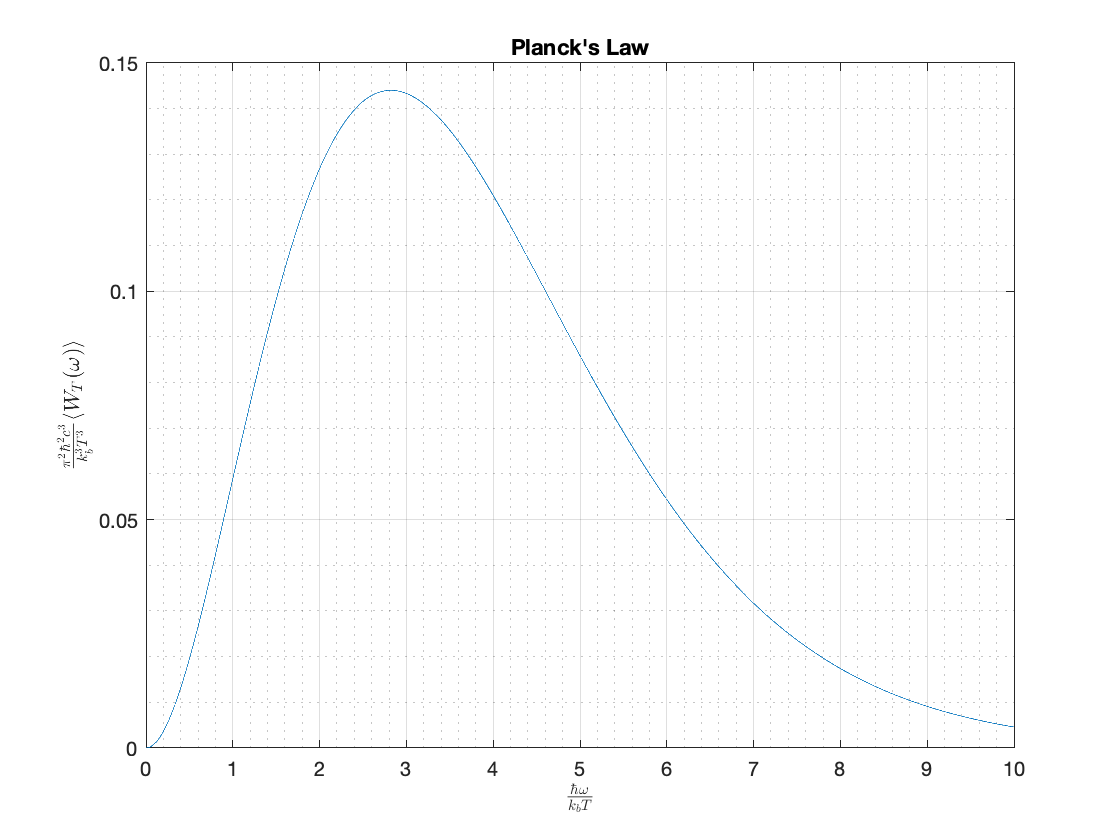


figure;
plot(omega, planck)
grid(gca, "minor")
grid on
xlabel('$\frac{\hbar \omega }{k_b T}$', 'Interpreter','latex')
ylabel('$\frac{\pi^2 \hbar^2 c^3}{k_b^3 T^3} \langle W_T (\omega) \rangle$', 'Interpreter', 'latex')
title("Planck's Law")

maxPlanck = max(planck);
maxOmega = find(planck==maxPlanck)*d_omega

maxOmega = 2.8215


lambda = c/maxOmega

lambda = 0.3544